## 1)

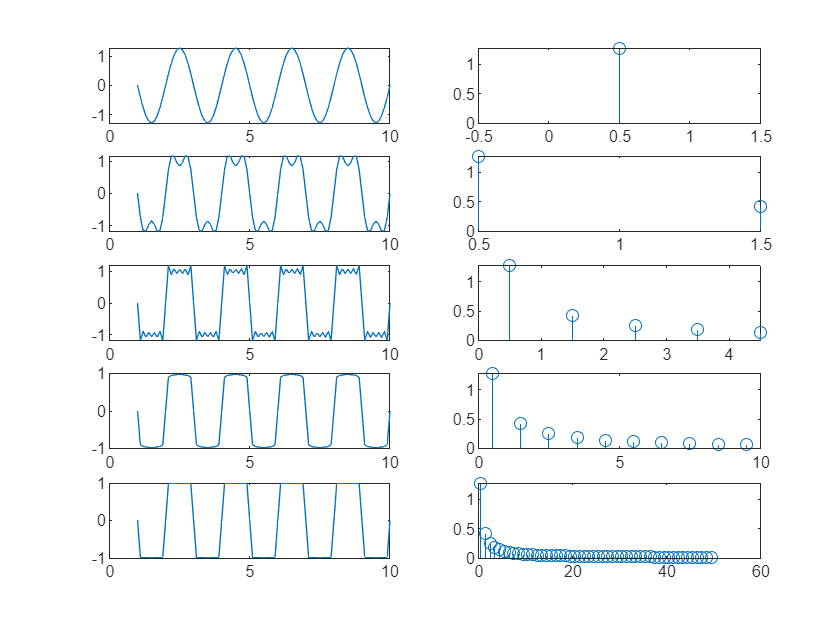

t=1:0.1:10;
% for i=1:length(t)
% y=4/(t(i)*pi);
% end
% plot(t,y);
A=1;
T=2;
w=(2*pi)/T;
figure(1)
subplot(5,2,1)
[~,coef,freq] = costam(A,t,w,1);
subplot(5,2,2)
stem(freq,coef);
subplot(5,2,3)
[~,coef,freq] = costam(A,t,w,3);
subplot(5,2,4)
stem(freq,coef);
subplot(5,2,5)
[~,coef,freq] = costam(A,t,w,10);
subplot(5,2,6)
stem(freq,coef);
subplot(5,2,7)
[~,coef,freq] = costam(A,t,w,20);
subplot(5,2,8)
stem(freq,coef);
subplot(5,2,9)
[y,coef,freq] = costam(A,t,w,100);
subplot(5,2,10)
stem(freq,coef);

## 2)

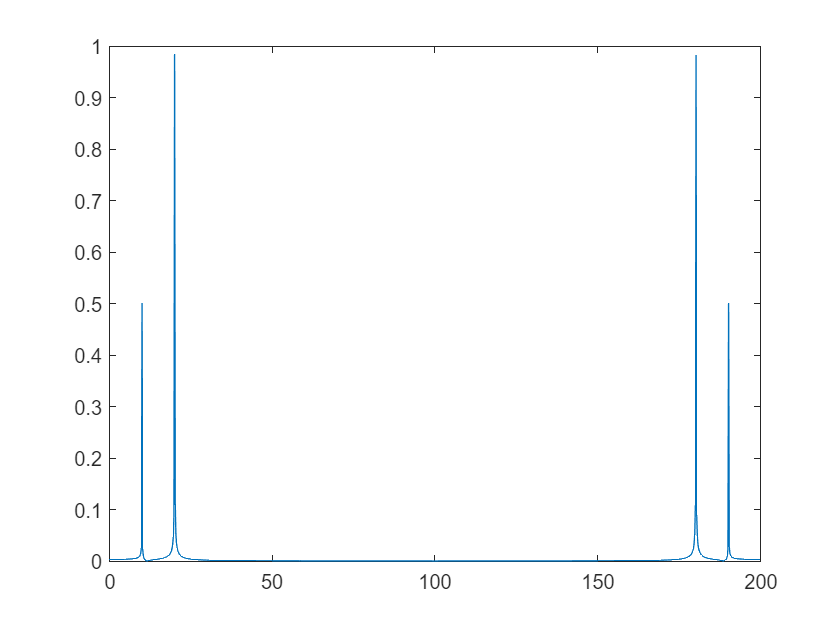

clear;
N=1001;
fs=200;
dt=1/fs;
df=fs/(N-1);

n=0;
f=df*(0:N-1);
t=dt*(0:N-1);
x = cos(2*pi*10*t)+2*cos(2*pi*20*t);

y=fft(x);
m=abs(y)/N;
p=rad2deg(unwrap(angle(y)));
figure(2);
plot(f,m);

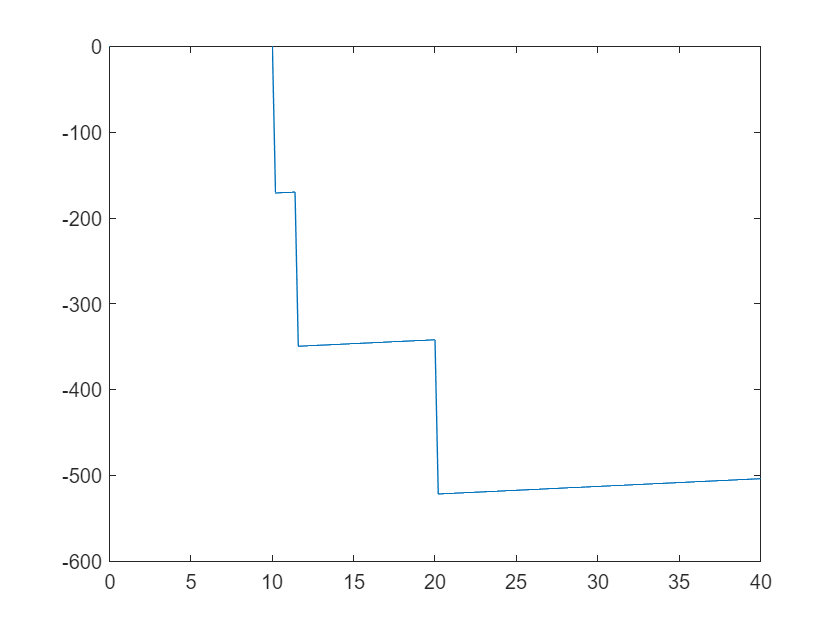

figure(3)
plot(f,p);
xlim([0 40]);
ylim([-600 0])

## 3)

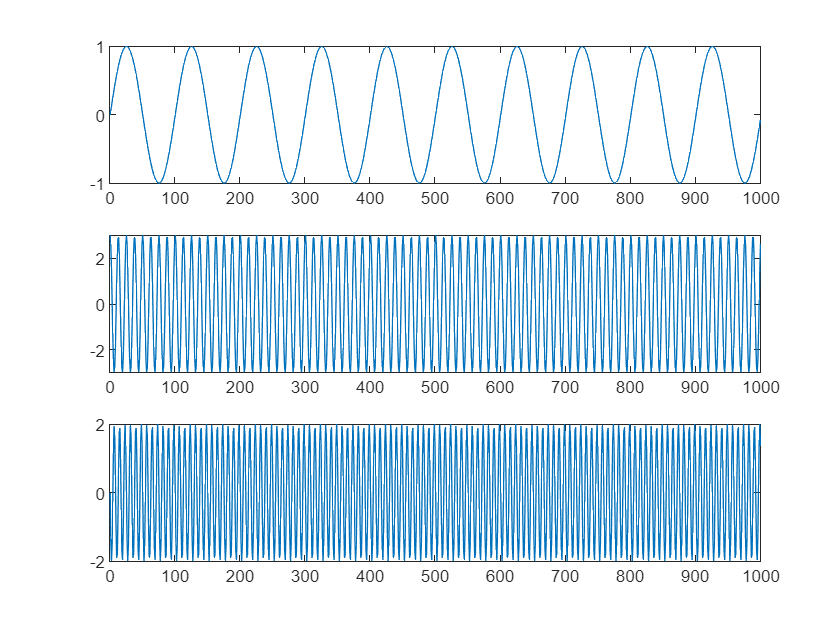

clear
N=1000;
fs=1000;
t=0:1/fs:(N/fs)-(1/fs);
x1=sin(2*pi*t*10);
x2=3*sin(2*pi*t*80+pi/2);
x3=2*sin(2*pi*t*120+pi);
figure(4)
subplot(3,1,1)
plot(x1)
subplot(3,1,2)
plot(x2)
subplot(3,1,3)
plot(x3)

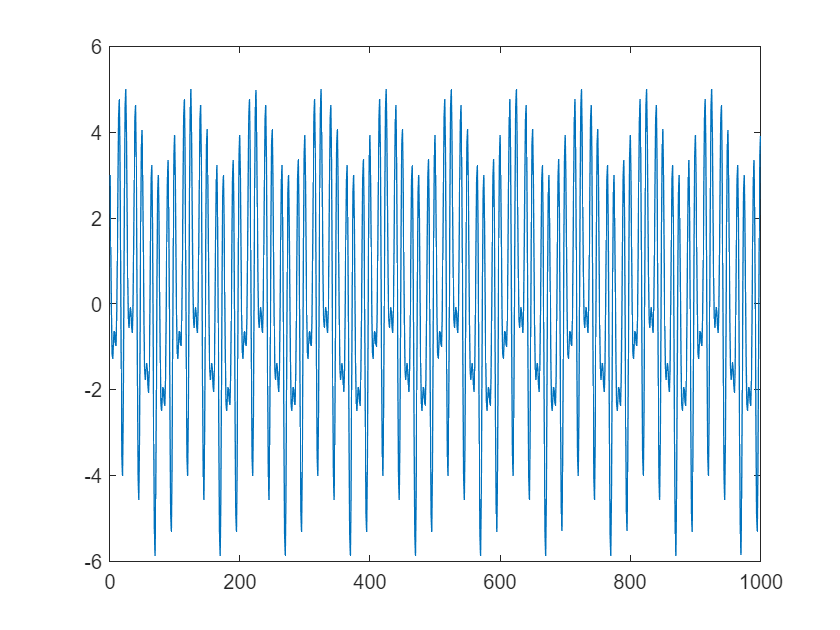


figure(5)
x4=x1+x2+x3;
plot(x4)

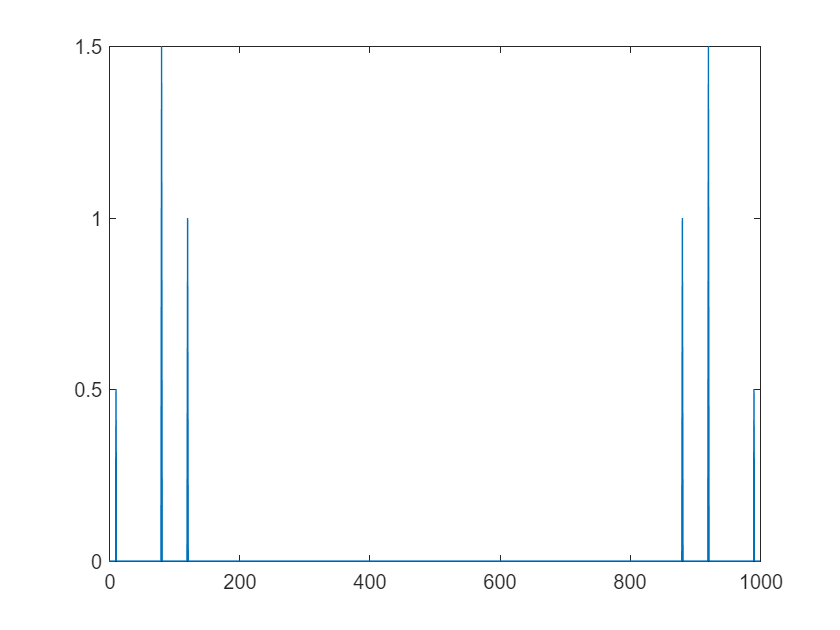

figure(6)
y=fft(x4);
m=abs(y)/N;
p=rad2deg(unwrap(angle(y)));
df=fs/(N);
f=df*(0:N-1);
plot(f,m);
xlim([0 1000]);

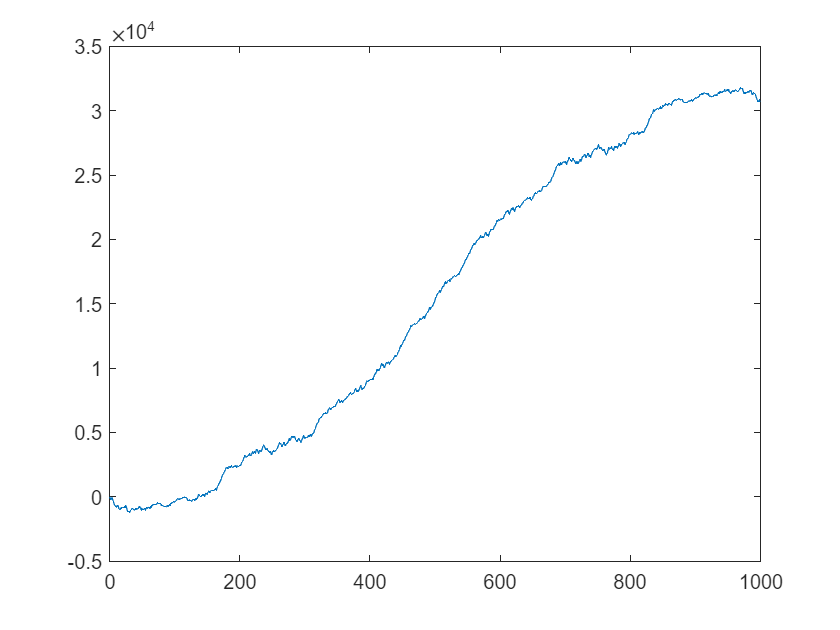


figure(7)
plot(f,p);
xlim([0 1000]);

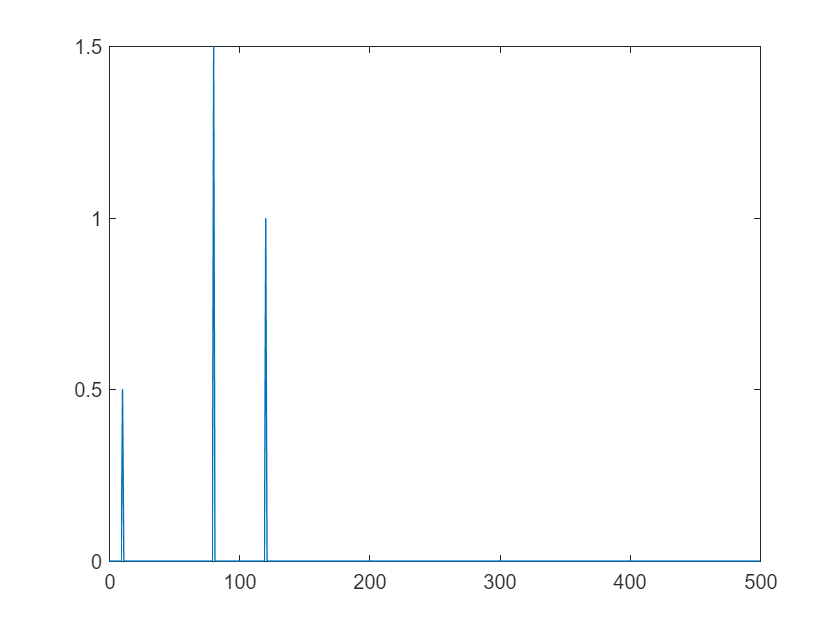


Fn = fs/2;               % Nyquist Frequency
figure(8)
plot(f,m);
xlim([0 500]);

figure(9)
plot(f,m);
xlim([0 500]);

## 4)

clear
i=0;
N=1000;

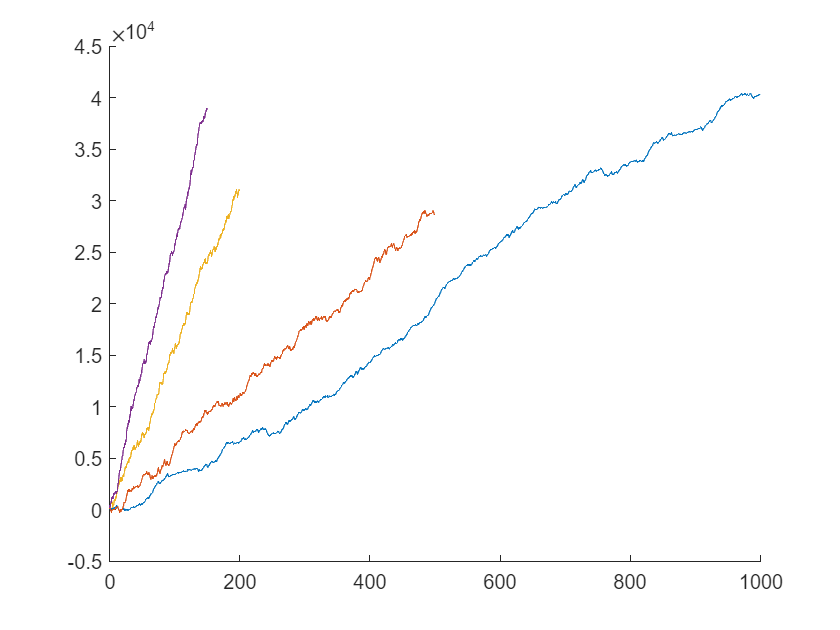

for fs=[1000 500 200 150]
    i=i+1;
    t(i,:)=0:1/fs:(N/fs)-(1/fs);
    x(i,:)=sin(2*pi*t(i,:)*120);
    y(i,:)=fft(x(i,:));
    m(i,:)=abs(y(i,:))/N;
    p(i,:)=rad2deg(unwrap(angle(y(i,:))));
    df(i,:)=fs/(N);
    f(i,:)=df(i,:)*(0:N-1);
    figure(10)
hold on
    plot(f(i,:),p(i,:));
    figure(11)
hold on
plot(f(i,:),m(i,:));
end

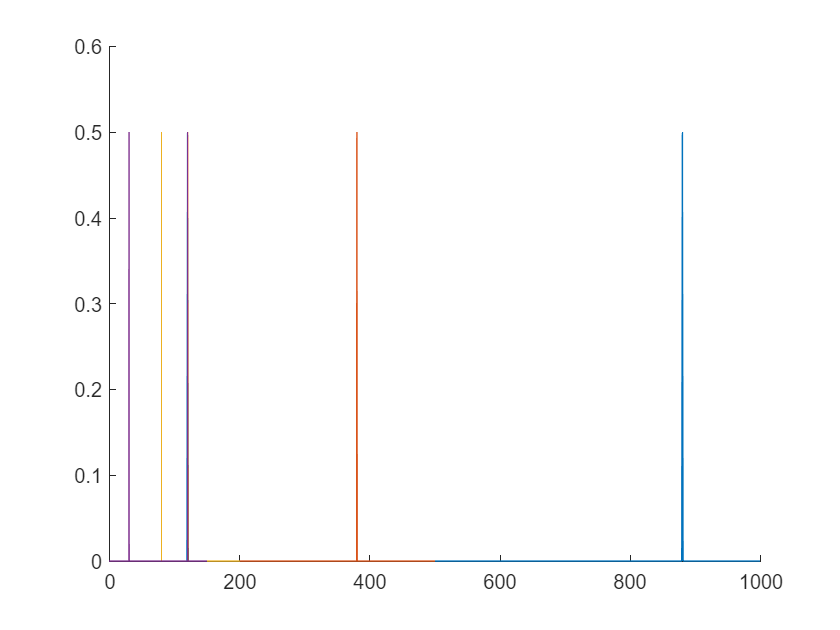

hold off